**Table 11-2 : Adiabatic PFR/PBR Algorithm**

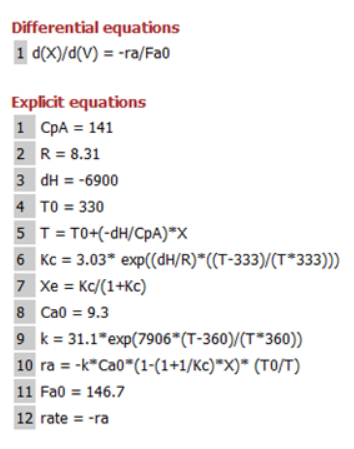

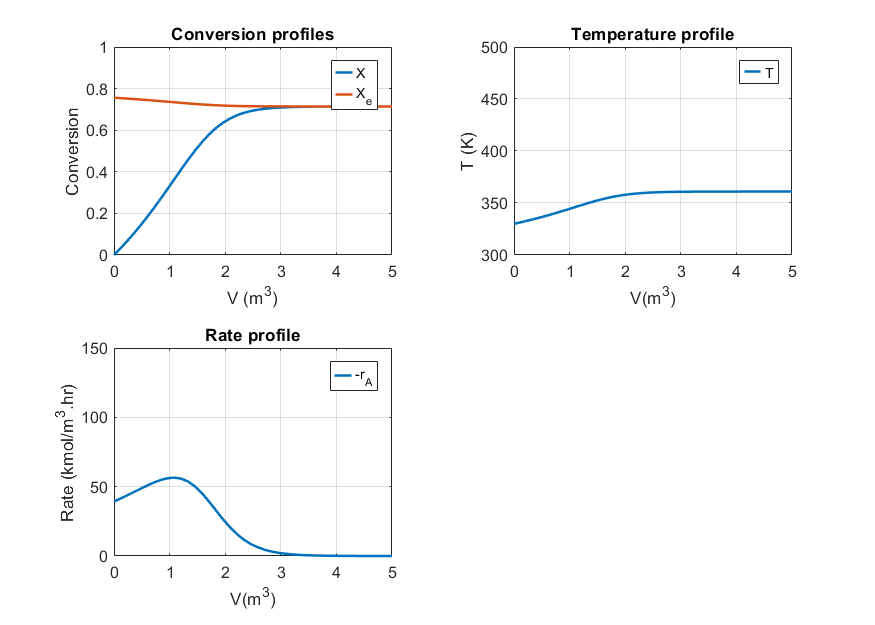

Vspan = [0 5]; % Range for the volume of the reactor 
y0 = [0]; % Initial values for the dependent variables i.e. X
Ca0=9.3;
T0=330;
dH=-6900;
Kc0=3.03;
FT0=163;
ya0=0.9;
Ea=65.7;
CpI=161;
CpA=141;
R = 8.31;
[v,y]=ode45(@(v,y)ODEfun(v,y,Ca0,T0,dH,Kc0,FT0,ya0,Ea,CpI,CpA,R),Vspan,y0);
z=size(y);
thetaI = (1 - ya0)/ya0;
Actenrgy = Ea*1000/8.31;
for i=1:z(1,1)
T(i,1) = T0-dH*y(i,1)/(CpA+thetaI*CpI);
Kc(i)= Kc0*exp(((dH/R)*((T(i) - 333)/(T(i)*333))));
k(i)= 31.1*exp(Actenrgy*(T(i)- 360)/(T(i)*360));
Xe(i)= Kc(i)./(1 + Kc(i)) ;
ra(i)= -k(i)*Ca0*(1 - (1 + 1/Kc(i))*y(i,1))* (T0/T(i)) ;
rate(i)= -ra(i);    
end
tiledlayout(2,2)
set (gcf,'Position',[0,0.1,700,500])
nexttile
plot(v,y(:,1),v,Xe(1:z(1,1)),'LineWidth',1.5)
legend('X','Xe')
xlabel('V (m^3)')
ylabel('Conversion')
leg=legend('X','X_e');
leg.ItemTokenSize=[10,10];
axis([0 5 0 1])
title('Conversion profiles')
grid on
nexttile
plot(v,T(1:z(1,1)),'LineWidth',1.5)
xlabel('V(m^3)')
ylabel('T (K)')
leg=legend('T');
leg.ItemTokenSize=[10,10];
axis([0 5 300 500])
title('Temperature profile')
grid on
nexttile
plot(v,rate(1:z(1,1)),'LineWidth',1.5)
xlabel('V(m^3)')
ylabel('Rate (kmol/m^3.hr)')
leg=legend('-r_A');
leg.ItemTokenSize=[10,10];
axis([0 5 0 150])
title('Rate profile')
grid on

function dYfuncvecdV = ODEfun(V,Yfuncvec,Ca0,T0,dH,Kc0,FT0,ya0,Ea,CpI,CpA,R); 
X = Yfuncvec(1); 
% Explicit equations
thetaI = (1 - ya0)/ya0;
Sumcp = CpA + thetaI*CpI;
T = T0-dH*X/(Sumcp);
Fa0 = ya0*FT0;
Actenrgy = Ea*1000/8.31;
Kc= Kc0*exp(((dH/R)*((T - 333)/(T*333))));
k= 31.1*exp(Actenrgy*(T- 360)/(T*360));
ra= -k*Ca0*(1 - (1 + 1/Kc)*X)* (T0/T) ;
% Differential equations
dXdV = -ra/Fa0; 
dYfuncvecdV =[dXdV]; 
end